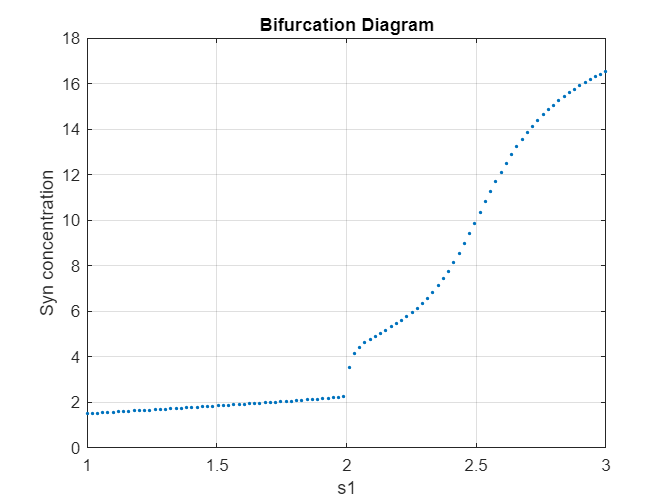

% Varying parameter values
s1_values = linspace(1, 3, 100);

% Set other parameter values
s2 = 1; s3 = 1;
k1 = 0.72; k2 = 0.72; k3 = 0.007; k4 = 0.007; k5 = 2.7;
dsyn = 15; ksyn = 8.5; k6 = 1; k7 = 0.5; k8 = 1; ERST = 2;
k9 = 2; k10 = 10; k11 = 0.4; k12 = 7; mTORT = 1;
Jbe = 1; k13 = 2; k14 = 4; k15 = 1; k16 = 10; k17 = 0.6; BecaT = 1;
Jca = 0.04; k18 = 1; k19 = 2; k20 = 2; k21 = 2; k22 = 4.5; CaspT = 1;

% Time span
tspan = [0 1000];

% Initialize matrices to store results
bifurcationValues = zeros(length(s1_values), 6);

% Loop through s1 values and simulate the system
for i = 1:length(s1_values)
    s1 = s1_values(i);

    % Create a function handle for the ODE system
    odefun_handle = @(t, y) odefun(t, y, s1, s2, s3, k1, k2, k3, k4, k5, s1, dsyn, ksyn, k6, k7, k8, ERST, k9, k10, k11, k12, mTORT, Jbe, k13, k14, k15, k16, k17, BecaT, Jca, k18, k19, k20, k21, k22, CaspT);

    % Solve the ODE system
    [~, y] = ode45(odefun_handle, tspan, [0; 0; 0; 1; 0; 0]);

    % Store the final values in the bifurcationValues matrix
    bifurcationValues(i, :) = y(end, :);
end

% Plot the bifurcation diagram
figure;
plot(s1_values, bifurcationValues(:, 2), '.');
xlabel('s1');
ylabel('Syn concentration');
title('Bifurcation Diagram');
grid on;